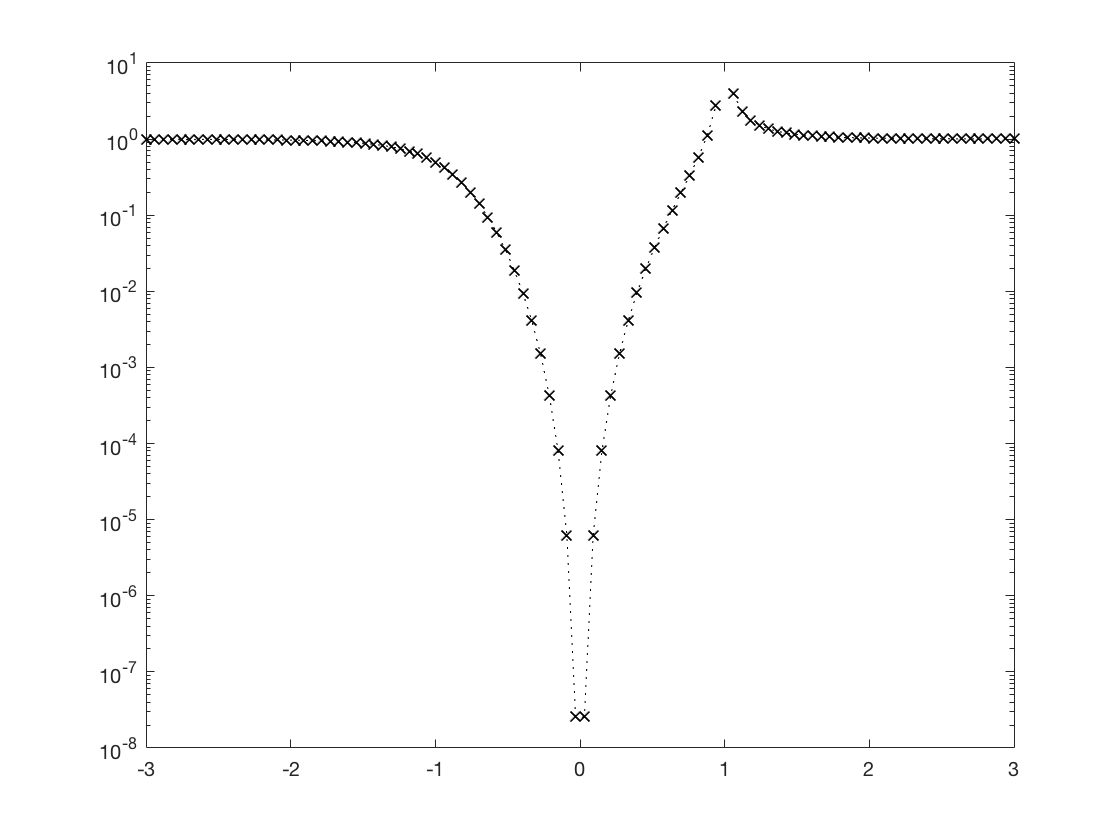

f = @(x) polyval([1 0 0 0 0 -1],x);
X = linspace(-2,2,100);
Y = f(X);
x = linspace(min(X)-1,max(X)+1,100);
error = abs(f(x)-linterp_bary(X,Y,x))./abs(f(x));
semilogy(x,error,'kx:');

% plot(x, f(x), 'ko:', x, linterp_bary(X, Y, x), 'rx:');
% xlim([-3 3]); ylim([eps le9]);

function y = linterp_bary(X, Y, x)
    w = ones(size(X));
    for i = 1:numel(X)
        for j = 1:numel(X)
            if i ~=j
                w(i) = w(i) * (X(i)-X(j));
            end     
        end
    end
    w = 1./w;
    yy = w./(x.'-X);
    y = sum(yy .* Y)/sum(yy);
end